l_0 = 0.5;
rho = 0.0254;

arm_series = ArmSeriesFactory.constant_2d_muscle_arm(N_segments, rho, l_0);
arm_series.set_mechanics(GinaMuscleMechanics(l_0));

% l_0 = 0.5;
% rho_outer_base = 0.06;
% rho_inner_base = 0.02;
% rho_outer_tip = 0.025;
% rho_inner_tip = 0.02;
% arm_series = ArmSeriesFactory.tapered_2d_antagonist_arm()

% optimize simple arm for a single target pose
Q = [0; -0.25; 0];
g_tip_goal = Pose2.hat([0.3; -0.2; 0]);

[residual, pressures] = evaluate_arm(arm_series, {g_tip_goal}, Q);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Elapsed time is 9.961183 seconds.


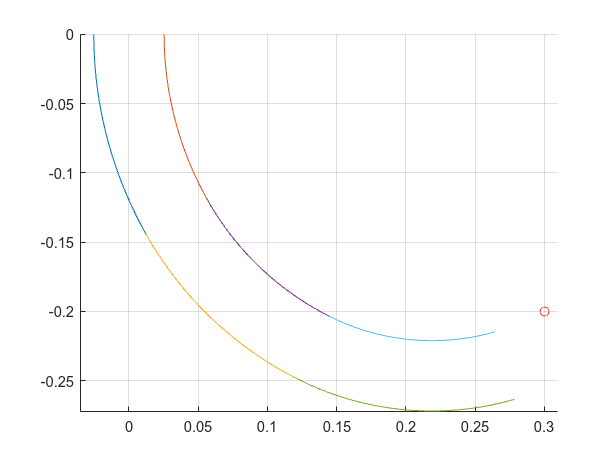

arm_series.solve_equilibrium_gina(pressures, Q, "print", false);
Plotter2D.plot_arm_series(arm_series, axes(figure()));
goal_coords = Pose2.vee(g_tip_goal);
scatter(goal_coords(1), goal_coords(2), 'ro');

disp(pressures)

    6.0557
   99.9966


% optimize simple arm for a list of target poses
Q = [0; 0; 0];
g_tip_goal_1 = Pose2.hat([0.3; -0.2; 0]);
g_tip_goal_2 = Pose2.hat([0.3; -0.3; 0]);
g_tip_goal_3 = Pose2.hat([0.3; -0.4; 0]);
g_targets = {g_tip_goal_1, g_tip_goal_2, g_tip_goal_3};

[residuals, pressures] = evaluate_arm(arm_series, g_targets, Q);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Elapsed time is 12.407385 seconds.

Local minimum possible. Constraints satisfied.

fminco

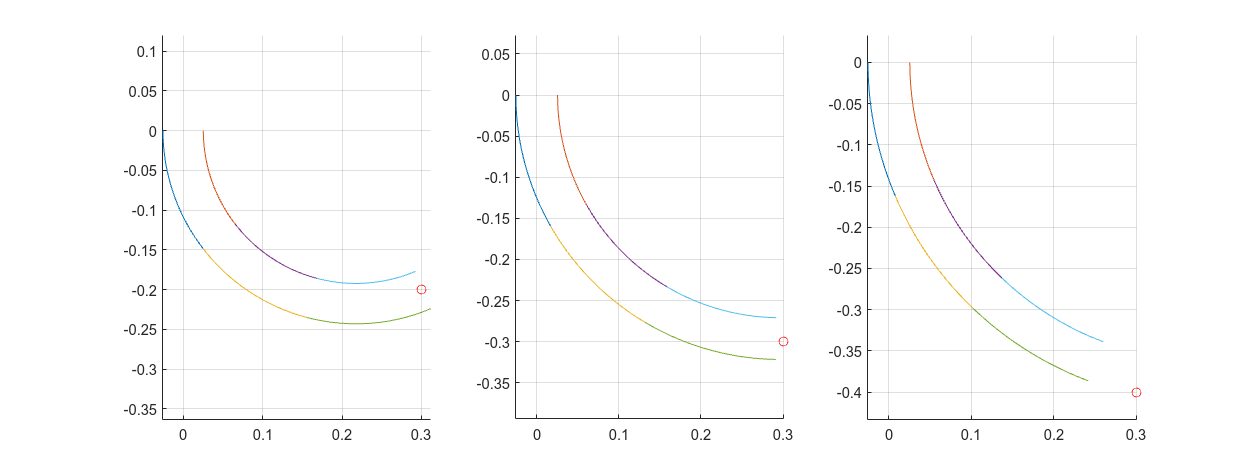


fig = figure();
set(fig, "Position", [0, 0, 1600, 600]);
for i = 1 : length(g_targets)
    ax = subplot(1, length(g_targets), i);
    arm_series.solve_equilibrium_gina(pressures(:, i), Q, "print", false);
    Plotter2D.plot_arm_series(arm_series, ax);
    
    g_target_i = g_targets{i};
    coords = Pose2.vee(g_target_i);
    scatter(coords(1), coords(2), 'ro');
end

disp(pressures)

   14.7007    0.0609    0.0111
   69.8948   34.7201   29.8610


Q = [0; -0.25; 0];
g_tip_goal_1 = Pose2.hat([0.3; -0.2; 0]);
g_tip_goal_2 = Pose2.hat([0.3; -0.3; 0]);
g_tip_goal_3 = Pose2.hat([0.3; -0.4; 0]);
g_targets = {g_tip_goal_1, g_tip_goal_2, g_tip_goal_3};

[residuals, pressures] = evaluate_arm(arm_series, g_targets, Q);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Elapsed time is 9.746761 seconds.

Local minimum found that satisfies the constraints.

Optimization 

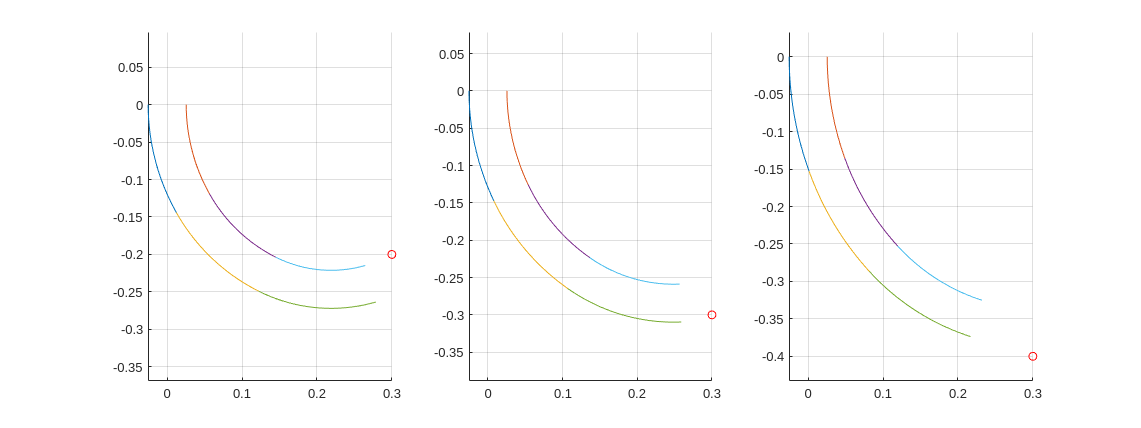


fig = figure();
set(fig, "Position", [0, 0, 1600, 600]);
for i = 1 : length(g_targets)
    ax = subplot(1, length(g_targets), i);
    arm_series.solve_equilibrium_gina(pressures(:, i), Q, "print", false);
    Plotter2D.plot_arm_series(arm_series, ax);
    
    g_target_i = g_targets{i};
    coords = Pose2.vee(g_target_i);
    scatter(coords(1), coords(2), 'ro');
end

disp(pressures)

    6.0557    3.4801    2.4172
   99.9966   71.2250   47.1775


figure()
arm_series.solve_equilibrium_gina([0; 100], Q)


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


ans =     0.4124    0.4175    0.4257
   -0.0000    0.0000    0.0000
    1.5331    1.7809    2.2401


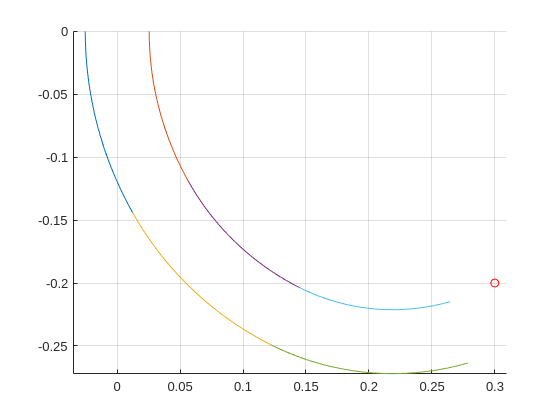

Plotter2D.plot_arm_series(arm_series, axes(figure()));
scatter(0.3, -0.2, 'ro');

Q = [0; -1; 0];
g_tip_goal_1 = Pose2.hat([0.3; -0.2; 0]);
g_tip_goal_2 = Pose2.hat([0.3; -0.3; 0]);
g_tip_goal_3 = Pose2.hat([0.3; -0.4; 0]);
g_targets = {g_tip_goal_1, g_tip_goal_2, g_tip_goal_3};

[residuals, pressures] = evaluate_arm(arm_series, g_targets, Q);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Elapsed time is 65.471257 seconds.

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

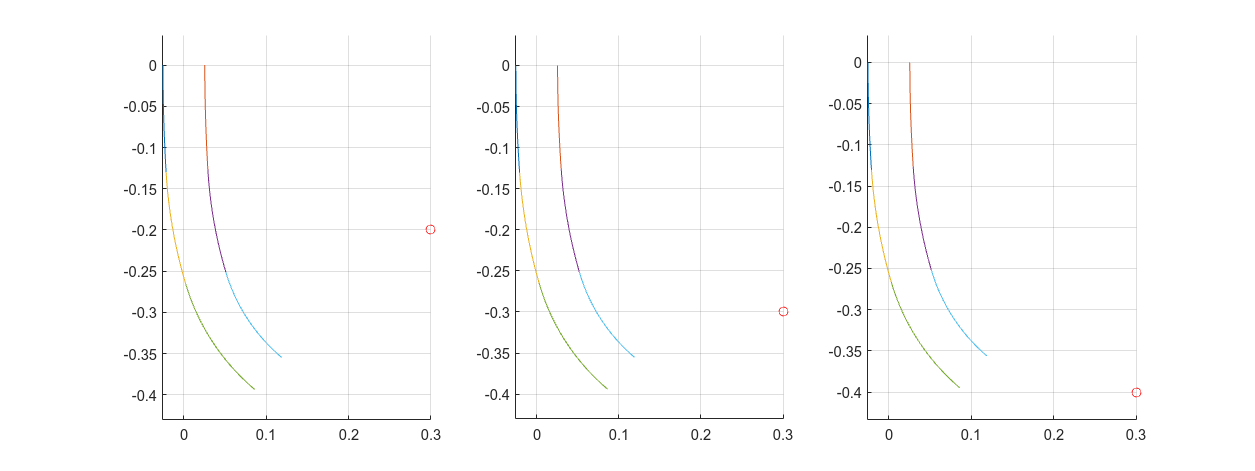


fig = figure();
set(fig, "Position", [0, 0, 1600, 600]);
for i = 1 : length(g_targets)
    ax = subplot(1, length(g_targets), i);
    arm_series.solve_equilibrium_gina(pressures(:, i), Q, "print", false);
    Plotter2D.plot_arm_series(arm_series, ax);
    
    g_target_i = g_targets{i};
    coords = Pose2.vee(g_target_i);
    scatter(coords(1), coords(2), 'ro');
end

function [residuals, pressures] = evaluate_arm(arm_series, g_targets, Q)
    
    function [pressures_optim, res] = optimize_input_to_reach_target(g_target)
        pressures_0 = zeros(arm_series.N_rods, 1);
        p_bounds = zeros(arm_series.N_rods, 2);
        for i = 1 : length(arm_series.segments(1).rods)
            rod_i = arm_series.segments(1).rods(i);
            p_bounds(i, :) = rod_i.mechanics.a_bounds;
        end

        function residual = evaluate_input(pressures)
            g_circ_right_eq = arm_series.solve_equilibrium_gina(pressures, Q, "print", false);
            tip_pose = arm_series.get_tip_pose(g_circ_right_eq);
            
            % Question: Should this be in SE2 or se2?
            v_error = Twist2.vee(logm(inv(tip_pose) * g_target));
    
            K = diag([1, 1, 0]);
            residual = v_error' * K * v_error;
        end

        opts = optimoptions("fmincon", "DiffMinChange", 0.1);
        tic
        [pressures_optim, res] = fmincon(@evaluate_input, pressures_0, [], [], [], [], p_bounds(:, 1), p_bounds(:, 2), [], opts);
        toc
    end

    residuals = zeros(length(g_targets), 1);
    pressures = zeros(arm_series.N_rods, length(g_targets));
    for i_target = 1 : length(g_targets)
        g_target_i = g_targets{i_target};
        [pressures_i, residual_i] = optimize_input_to_reach_target(g_target_i);
        pressures(:, i_target) = pressures_i;
        residuals(:, i_target) = residual_i;
    end
end